**Experiment - 6                                                                        Date - 15 / 3 / 24**

**Aim - Design the Finite Impulse Response (FIR) digital filters for low pass , **

**high pass , band pass , and band stop responses.**

**Laboratory Exercise **

A) Using the function fir1() , design a linear - phase FIR lowpass filter meeting the specifications : - passband edge = 2kHz , stopband edge = 2.5kHz , passband ripple delp = 0.005 , stopband ripple dels = 0.005 , and sampling rate of 10kHz .

Show the filter coefficients in a tabular form . Does your design meet the specifications ? If it does not  , adjust the filter order until the design meets specifications . Based on the results , comments upon the frequency response for chosed order of filter .

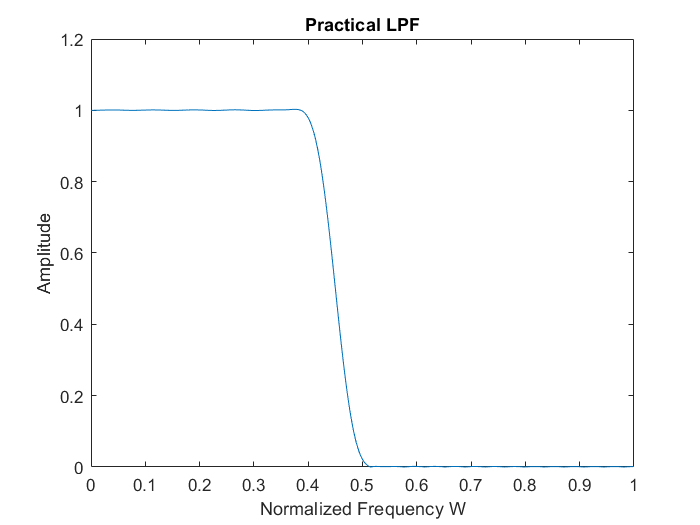

%[n,Wn,beta,ftype] = kaiserord(f,a,dev)
% fsamp = 8000;
% fcuts = [1000 1500];
% mags = [1 0];
% devs = [0.05 0.01];
% 
% [n,Wn,beta,ftype] = kaiserord(fcuts,mags,devs,fsamp);

clc ; clear all ; close all ;

Wp = 2000 ; Ws = 2500 ; delp = 0.005 ; dels = 0.005 ; fs = 10000 ;
fcuts = [Wp Ws] ; mags = [1 0] ; devs = [delp dels] ;
[N , Wn] = kaiserord(fcuts , mags , devs , fs) ;

b = fir1(N , Wn) ;
[H,W] = freqz(b,1) ; grid on ; plot(W/pi , abs(H)) ; title("Practical LPF") ;  ylabel("Amplitude") ; xlabel("Normalized Frequency W") ;

%axis([0 1 0.96 1.04]) ;

%Check for N = 44 and 60 as N = 54
%b = fir1(60 , Wn) ;
%[H,W] = freqz(b,1) ; grid on ; title("Practical LPF") ; subplot(2,1,2) ; plot(W/pi , abs(H)) ; ylabel("Amplitude") ; xlabel("Normalized Frequency W") ;

**Inference : - Here , we learnt to use kaiserord() and fir1() functions . We learnt how practical or FIR Low Pass Filter is designed in MATLAB . We also found that N = 54 (Order) , and tried to increase the order manually to get near to the requirement specified .We also checked the validity of the filter using data tips .  Further increase in the order will take us near to the ideal response but on the cost of increase in Hardware required  .**